# Excitation light calibration and fluorescence linearity

ieInit;
waves = 380:5:750;


### Spectral energy

These are measurements of the spectral energy in the 405, 415 and 450 nm lights driven by 1000 mA.  This is the maximum current we couuld apply. We used less current in the actual measurements.

Note that we also measured the spectral energy at different intensities, but not exactly at the intensities that we used in the experiments. So we probably need to make measurements of the lights at the intensity levels we used when we made measurements of tongue and lip fluorescence.

Note also that there is thermal energy in the lights at wavelengths greater than 680 nm.  This means that **we need to have an NIR blocking filter on the cameras**

And surely we did not put a 450 nm SPF on the 450 nm LED, did we? This must be a typo. Notice that some of the 450 nm light passes through the 475 nm filter (see light leakage section below).  We did not worry so much about the 450 nm light because we knew we planned to use a 415 nm light. There is also thermal energy.  So,  in analyzing the fluorescence measurements made with the 450 nm excitation light, we should **only consider spectral energy between 500 and 680 nm**

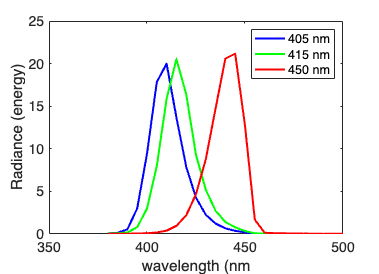

ieNewGraphWin;
data = ieReadSpectra('spd-2024-03-07-Calib-405nm450SPF-1000mA.mat',waves);  plot(waves,data,'b','LineWidth',2); hold on
% 415 415nm_910mA.mat
data = ieReadSpectra('spd-2024-03-07-calib-415nm450SPF-1000mA.mat',waves);  plot(waves,data,'g','LineWidth',2);
% 450 450nm_870mA.mat
data = ieReadSpectra('spd-2024-03-07-Calib-450nm450SPF-1000mA.mat',waves); plot(waves,data,'r','LineWidth',2);
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([350 500]);
legend('405 nm', '415 nm', '450 nm');

% title('Spectral energy in the excitation lights with 450 nm shortpass filter')

### Light leakage

The led lights have some (albeit) small amounts of spectral energy greater than 475 nm.  Thus, it is conceivable that some of the light that is measured by the spectrophotometer equipped with a 475 nm filter, may include light that is reflected from the tissue.  For measurements of tissue fluorescence, reflected light consitutes noise.  

In order to assess how much signal could be attributed to noise, we made the following calibration measurements.

- We placed a white surface 10 cm from the excitation light (the same distance that was used to illuminate the tongue and lower-lip area)

- We illluminated the white surface with the excitation lights and measured the light reflected from the surface using the spectrophotometer with a 475 nm light

- Note that this is the amount of light reflected from a white surface reaching the spectrophotometer.  To calculate how much light could have been reflected from the tongue, for example, we multiplied the light reflected from white surface with the mean of tongue reflectance measurements obtained from 12 participants.  This later calculation is an estimate of the maximum amount of light that could be reflected from the tongue or our participants. 

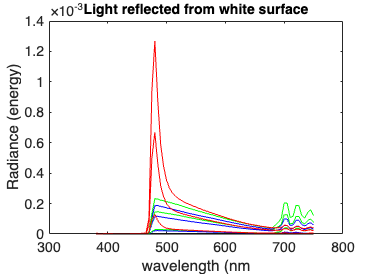

ieNewGraphWin;
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_90mA.mat',waves); plot(waves,data,'b'); hold on;
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_560mA.mat',waves); plot(waves,data,'b');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_980mA.mat',waves); plot(waves,data,'b');

data = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_80mA.mat',waves); plot(waves,data,'g');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_460mA.mat',waves); plot(waves,data,'g'); 
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_910mA.mat',waves); plot(waves,data,'g');

data = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_90mA.mat',waves); plot(waves,data,'r');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_480mA.mat',waves); plot(waves,data,'r');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_870mA.mat',waves); plot(waves,data,'r');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-completeblack.mat',waves); plot(waves,data,'k');  
title('Light reflected from white surface')
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');

### Predicted reflectance

To calculate how much light could have been reflected from the tongue, for example, we multiplied the light reflected from white surface with the mean of tongue reflectance measurements obtained from 12 participants.  This later calculation is an estimate of the maximum amount of light that could be reflected from the tongue or our participants. 


tongue = ieReadSpectra('tongue.mat',waves); 
% figure; plot(waves,tongue,'k'); hold on;
meanTongueReflectance = mean(tongue,2);
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_80mA.mat',waves); 
predictedTongueReflectance_415nm_80mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_460mA.mat',waves); 
predictedTongueReflectance_415nm_460mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_910mA.mat',waves); 
predictedTongueReflectance_415nm_910mA = whiteSurface .* meanTongueReflectance;

Now compare the tongue radiance measurements with predicted tongue reflectance.  

We plot the amount of light we predict to be reflected from the tongue when it was illuminated with the highest intensity light. And we compare it to the light that is measured from the **tongue illuminated with the 415 nm light at 4 different light intensities.**  You can see that the estimated maximum reflected light (when the light was at maximum intensity ) is less than the light measured from the tongue at the lowest intensity.  Thus, we can conclude that at all intensities, the reflected light is noise

### Tongue radiance for 415 nm at 4 levels: 80, 170, 460, 910 mA

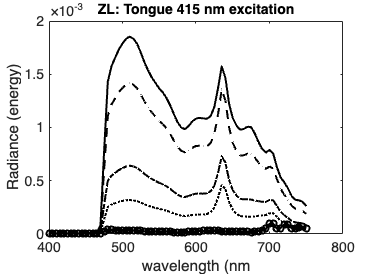

% Zhenyi
ieNewGraphWin;
Z_tongue = ieReadSpectra('spd-2024-03-07-Z-Tongue-415nm450SPF-80mA-R01.mat',waves);     plot(waves,Z_tongue,'k:','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-07-Z-Tongue-415nm450SPF-170mA-R01.mat',waves);	plot(waves,Z_tongue,'k-.','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-07-Z-Tongue-415nm450SPF-460mA-R01.mat',waves);	plot(waves,Z_tongue,'k--','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-07-Z-Tongue-415nm450SPF-910mA-R01.mat',waves);    plot(waves,Z_tongue,'k','LineWidth',2); hold on;  
plot(waves,predictedTongueReflectance_415nm_910mA,'k-o','LineWidth',2); 
title ('ZL: Tongue 415 nm excitation');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

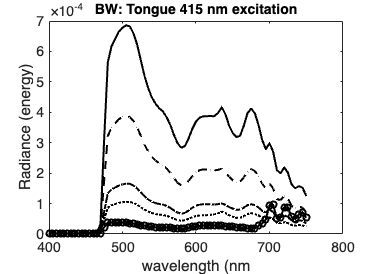


% Brian  
ieNewGraphWin;
B_tongue = ieReadSpectra('spd-2024-03-07-B-tongue-415nm450SPF-80mA-R01.mat',waves);plot(waves,B_tongue,'k:','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-07-B-tongue-415nm450SPF-170mA-R01.mat',waves);    plot(waves,B_tongue,'k-.','LineWidth',2); hold on;	
B_tongue = ieReadSpectra('spd-2024-03-07-B-tongue-415nm450SPF-460mA-R02.mat',waves);    plot(waves,B_tongue','k--','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-07-B-tongue-415nm450SPF-910mA-R01.mat',waves);    plot(waves,B_tongue,'k','LineWidth',2); hold on;
plot(waves,predictedTongueReflectance_415nm_910mA,'k-o','LineWidth',2); 
title('BW: Tongue 415 nm excitation');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

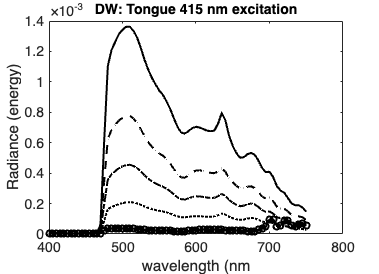


% Doug 
ieNewGraphWin;
D_tongue = ieReadSpectra('spd-2024-03-08-D-tongue-415nm450spf_80mA-R01.mat',waves); plot(waves,D_tongue,'k:','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-08-D-tongue-415nm450spf_170mA-R01.mat',waves); plot(waves,D_tongue,'k-.','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-08-D-tongue-415nm450spf_460mA-R02.mat',waves); plot(waves,D_tongue,'k--','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-08-D-tongue-415nm450spf_910mA-R01.mat',waves); plot(waves,D_tongue,'k','LineWidth',2); hold on; 
plot(waves,predictedTongueReflectance_415nm_910mA,'k-o','LineWidth',2); 
title('DW: Tongue 415 nm excitation');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

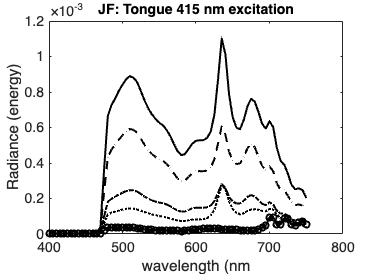


%% Joyce 
% Before lunch (tongue 415 at different intensities)
ieNewGraphWin;
J_tongue = ieReadSpectra('spd-2024-03-08-J-415nm450spf-80mA-R01.mat',waves);     plot(waves,J_tongue,'k:','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-08-J-415nm450spf-170mA-R01.mat',waves);    plot(waves,J_tongue,'k-.','LineWidth',2); hold on;	
J_tongue = ieReadSpectra('spd-2024-03-08-J-415nm450spf-460mA-R01.mat',waves);    plot(waves,J_tongue,'k--','LineWidth',2); hold on;		
J_tongue = ieReadSpectra('spd-2024-03-08-J-415nm450spf-910mA-R01.mat',waves);    plot(waves,J_tongue,'k','LineWidth',2);
plot(waves,predictedTongueReflectance_415nm_910mA,'k-o','LineWidth',2); 
title('JF: Tongue 415 nm excitation');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

We did not measure reflectance from the lower lip, but we could if we wanted to

We did measure fluorescence from the lower lip area, shown below

### Lip radiance for 415 nm at 4 levels: 80, 170, 460, 910 mA

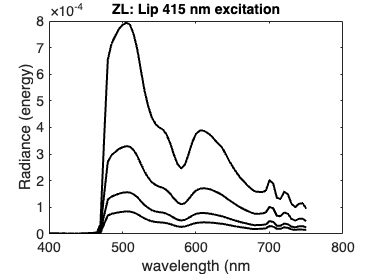

% Zhenyi
ieNewGraphWin;
Z_lip = ieReadSpectra('spd-2024-03-07-Z-lip-415nm450SPF-80mA-R01.mat',waves);  plot(waves,Z_lip,'k','LineWidth',2); hold on;
%Z_lip = ieReadSpectra('spd-2024-03-07-Z-lip-415nm450SPF-80mA-R02.mat',waves);  plot(waves,Z_lip,'k:','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-07-Z-lip-415nm450SPF-170mA-R01.mat',waves);  plot(waves,Z_lip,'k','LineWidth',2); hold on;
%Z_lip = ieReadSpectra('spd-2024-03-07-Z-lip-415nm450SPF-170mA-R02.mat',waves); plot(waves,Z_lip,'k:','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-07-Z-lip-415nm450SPF-460mA-R01.mat',waves);  plot(waves,Z_lip,'k','LineWidth',2); hold on;
%Z_lip = ieReadSpectra('spd-2024-03-07-Z-lip-415nm450SPF-460mA-R02.mat',waves);  plot(waves,Z_lip,'k:','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-07-Z-lip-415nm450SPF-910mA-R01.mat',waves);  plot(waves,Z_lip,'k','LineWidth',2); hold on;
%Z_lip = ieReadSpectra('spd-2024-03-07-Z-lip-415nm450SPF-910mA-R02.mat',waves);  plot(waves,Z_lip,'k:','LineWidth',2); hold on;
title('ZL: Lip 415 nm excitation');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

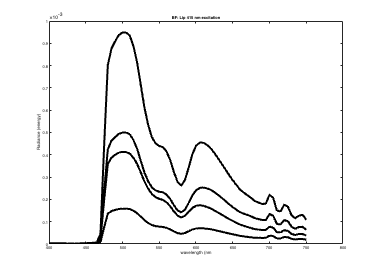


% Brian
ieNewGraphWin;
B_lip = ieReadSpectra('spd-2024-03-07-B-lip-415nm450SPF-80mA-R01.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
%B_lip = ieReadSpectra('spd-2024-03-07-B-lip-415nm450SPF-80mA-R02.mat',waves);   plot(waves,B_lip,'k:','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-07-B-lip-415nm450SPF-170mA-R01.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
%B_lip = ieReadSpectra('spd-2024-03-07-B-lip-415nm450SPF-170mA-R02.mat',waves);   plot(waves,B_lip,'k:','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-07-B-lip-415nm450SPF-460mA-R01.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
%B_lip = ieReadSpectra('spd-2024-03-07-B-lip-415nm450SPF-460mA-R02.mat',waves);   plot(waves,B_lip,'k:','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-07-B-lip-415nm450SPF-910mA-R01.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
% B_lip = ieReadSpectra('spd-2024-03-07-B-lip-415nm450SPF-910mA-R02.mat',waves);   plot(waves,B_lip,'k:','LineWidth',2); hold on;
title('BF: Lip 415 nm excitation');
fontsize(gca,4,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

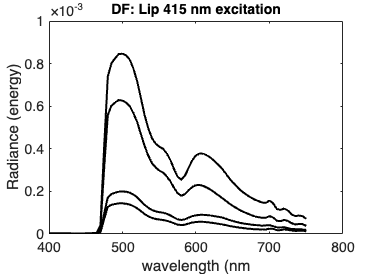


% Doug
ieNewGraphWin;
D_lip = ieReadSpectra('spd-2024-03-08-D-lip-415nm450spf_170mA-R01.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
%D_lip = ieReadSpectra('spd-2024-03-08-D-lip-415nm450spf_170mA-R02.mat',waves);   plot(waves,D_lip,'k:','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-08-D-lip-415nm450spf_460mA-R01.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
%D_lip = ieReadSpectra('spd-2024-03-08-D-lip-415nm450spf_460mA-R02.mat',waves);   plot(waves,D_lip,'k:','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-08-D-lip-415nm450spf_80mA-R01.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
%D_lip = ieReadSpectra('spd-2024-03-08-D-lip-415nm450spf_80mA-R02.mat',waves);   plot(waves,D_lip,'k:','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-08-D-lip-415nm450spf_910mA-R01.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
%D_lip = ieReadSpectra('spd-2024-03-08-D-lip-415nm450spf_910mA-R02.mat',waves);   plot(waves,D_lip,'k:','LineWidth',2); hold on;
title('DF: Lip 415 nm excitation');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

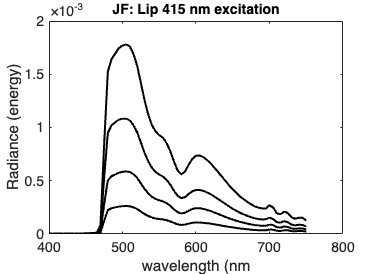


% Joyce
ieNewGraphWin;
J_lip = ieReadSpectra('spd-2024-03-08-J-lip-415nm450spf-80mA-R01.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
%J_lip = ieReadSpectra('spd-2024-03-08-J-lip-415nm450spf-80mA-R02.mat',waves);   plot(waves,J_lip,'k:','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-08-J-lip-415nm450spf-170mA-R01.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
%J_lip = ieReadSpectra('spd-2024-03-08-J-lip-415nm450spf-170mA-R02.mat',waves);   plot(waves,J_lip,'k:','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-08-J-lip-415nm450spf-460mA-R01.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
%J_lip = ieReadSpectra('spd-2024-03-08-J-lip-415nm450spf-460mA-R02.mat',waves);   plot(waves,J_lip,'k:','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-08-J-lip-415nm450spf-910mA-R01.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
%J_lip = ieReadSpectra('spd-2024-03-08-J-lip-415nm450spf-910mA-R02.mat',waves);   plot(waves,J_lip,'k:','LineWidth',2); hold on;
title('JF: Lip 415 nm excitation');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy)');	
xlim([400 800]);

### Tongue radiance at different levels for 405, 415 and 450 nm lights

There are some missing data, but nonetheless, good to look at

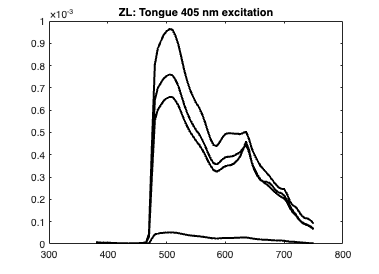


% Zhenyi
ieNewGraphWin; 
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-405nm_tongue_90mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-405nm_tongue_560mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-405nm_tongue_980mA-1.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-405nm_tongue_980mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
title('ZL: Tongue 405 nm excitation');

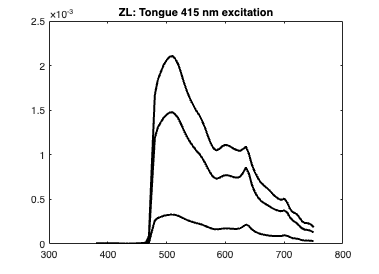


ieNewGraphWin;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-415nm_Tongue_80mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-415nm_Tongue_460mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-415nm_Tongue_910mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
title('ZL: Tongue 415 nm excitation');

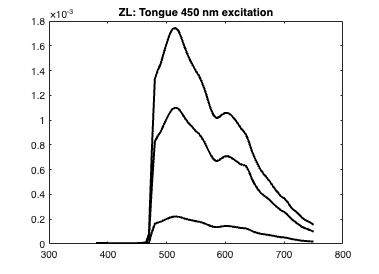


ieNewGraphWin; 
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-450nm_tongue_90mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-450nm_tongue_480mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
Z_tongue = ieReadSpectra('spd-2024-03-14-Z-450nm_tongue_870mA.mat',waves);   plot(waves,Z_tongue,'k','LineWidth',2); hold on;
title('ZL: Tongue 450 nm excitation');

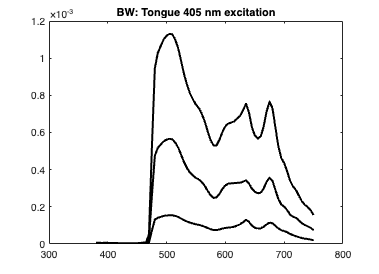


% Brian
ieNewGraphWin; 
B_tongue = ieReadSpectra('spd-2024-03-19-B_405nm_tongue_90mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_405nm_tongue_560mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_405nm_tongue_980mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
title('BW: Tongue 405 nm excitation');

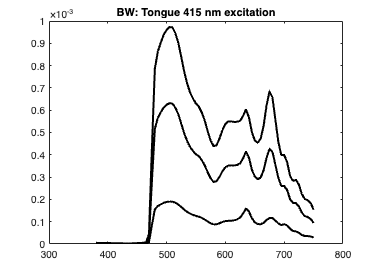


ieNewGraphWin; 
B_tongue = ieReadSpectra('spd-2024-03-19-B_415nm_tongue_80mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_415nm_tongue_460mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_415nm_tongue_910mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
title('BW: Tongue 415 nm excitation');

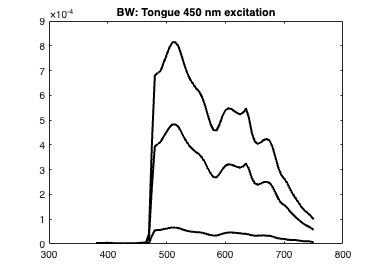


ieNewGraphWin; 
B_tongue = ieReadSpectra('spd-2024-03-19-B_450nm_tongue_90mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_450nm_tongue_480mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
B_tongue = ieReadSpectra('spd-2024-03-19-B_450nm_tongue_870mA.mat',waves);   plot(waves,B_tongue,'k','LineWidth',2); hold on;
title('BW: Tongue 450 nm excitation');

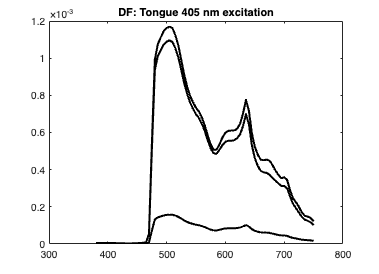


% Doug
ieNewGraphWin; 
D_tongue = ieReadSpectra('spd-2024-03-19-D_4050nm_tongue_90mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_405nm_tongue_90mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_4050nm_tongue_980mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_405nm_tongue_980mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_405nm_tongue_560mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
title('DF: Tongue 405 nm excitation');

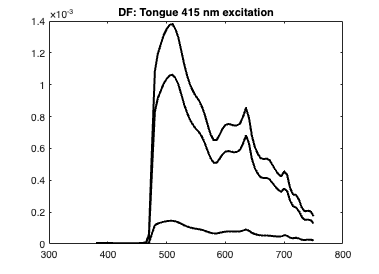


ieNewGraphWin; 
D_tongue = ieReadSpectra('spd-2024-03-19-D_415nm_tongue_80mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_4150nm_tongue_80mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_415nm_tongue_460mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_415nm_tongue_910mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
title('DF: Tongue 415 nm excitation');

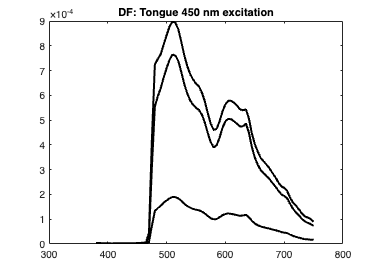


ieNewGraphWin; 
D_tongue = ieReadSpectra('spd-2024-03-19-D_450nm_tongue_90mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_450nm_tongue_480mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
D_tongue = ieReadSpectra('spd-2024-03-19-D_450nm_tongue_870mA.mat',waves);   plot(waves,D_tongue,'k','LineWidth',2); hold on;
title('DF: Tongue 450 nm excitation');

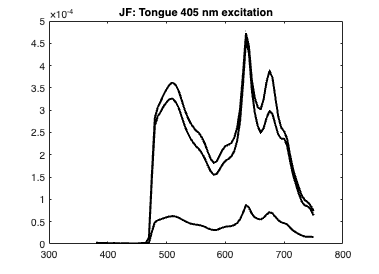


% Joyce
ieNewGraphWin; 
J_tongue = ieReadSpectra('spd-2024-03-12-11-405nm-J-tongue-90mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-11-405nm-J-tongue-560mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-11-405nm-J-tongue-980mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
title('JF: Tongue 405 nm excitation');

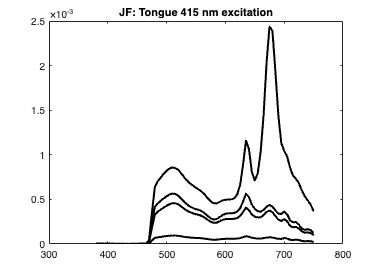


ieNewGraphWin; 
J_tongue = ieReadSpectra('spd-2024-03-12-11-415nm-J-tongue-80mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-11-415nm-J-tongue-460mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-11-415nm-J-tongue-910mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-19-J-tongue-415nm-1000mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
title('JF: Tongue 415 nm excitation');

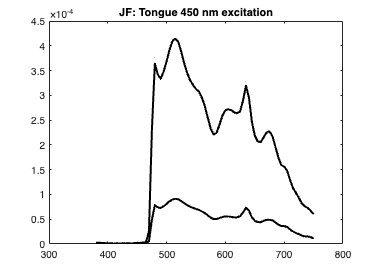


ieNewGraphWin; 
J_tongue = ieReadSpectra('spd-2024-03-12-450nm-J-tongue-90mA.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
J_tongue = ieReadSpectra('spd-2024-03-12-450nm-J-tongue-460mA-1.mat',waves);   plot(waves,J_tongue,'k','LineWidth',2); hold on;
title('JF: Tongue 450 nm excitation');

### Lip radiance at different levels for 405, 415 and 450 nm lights

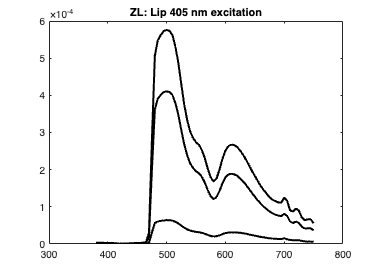

% Zhenyi
ieNewGraphWin;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-405nm_lip_90mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-405nm_lip_560mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-405nm_lip_980mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
title('ZL: Lip 405 nm excitation');

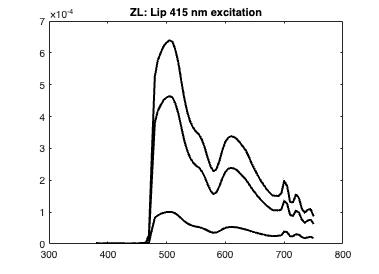


ieNewGraphWin; 
Z_lip = ieReadSpectra('spd-2024-03-14-Z-415nm_lip_80mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-415nm_lip_460mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-415nm_lip_910mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
title('ZL: Lip 415 nm excitation');

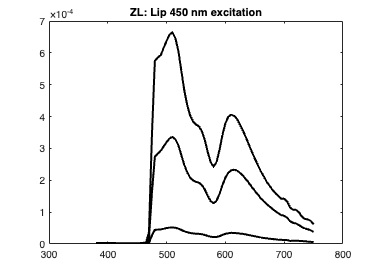


ieNewGraphWin; 
Z_lip = ieReadSpectra('spd-2024-03-14-Z-450nm_lip_90mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-450nm_lip_480mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
Z_lip = ieReadSpectra('spd-2024-03-14-Z-450nm_lip_870mA.mat',waves);   plot(waves,Z_lip,'k','LineWidth',2); hold on;
title('ZL: Lip 450 nm excitation');

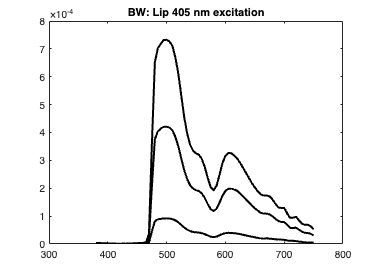


% Brian
ieNewGraphWin; 
B_lip = ieReadSpectra('spd-2024-03-19-B_405nm_lip_560mA.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_405nm_lip_90mA.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_405nm_lip_980mA.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
title('BW: Lip 405 nm excitation');

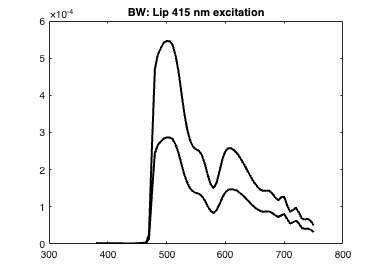


ieNewGraphWin; 
B_lip = ieReadSpectra('spd-2024-03-19-B_415nm_lip_460mA.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_415nm_lip_910mA.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
title('BW: Lip 415 nm excitation');

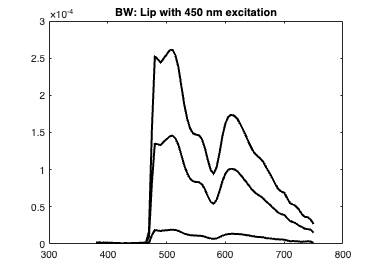


ieNewGraphWin; 
B_lip = ieReadSpectra('spd-2024-03-19-B_450nm_lip_90mA.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_450nm_lip_480mA.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
B_lip = ieReadSpectra('spd-2024-03-19-B_450nm_lip_870mA.mat',waves);   plot(waves,B_lip,'k','LineWidth',2); hold on;
title('BW: Lip with 450 nm excitation');

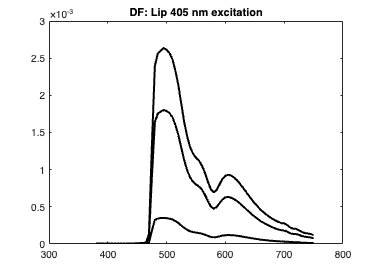


% Doug
ieNewGraphWin; 
D_lip = ieReadSpectra('spd-2024-03-19-D_405nm_lip_560mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_405nm_lip_90mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_405nm_lip_980mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
title('DF: Lip 405 nm excitation');

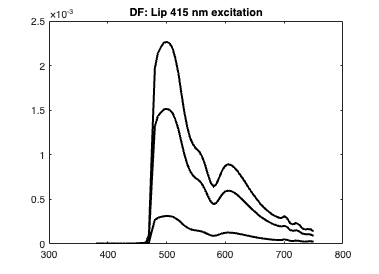


ieNewGraphWin; 
D_lip = ieReadSpectra('spd-2024-03-19-D_415nm_lip_90mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_415nm_lip_460mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_415nm_lip_910mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
title('DF: Lip 415 nm excitation');

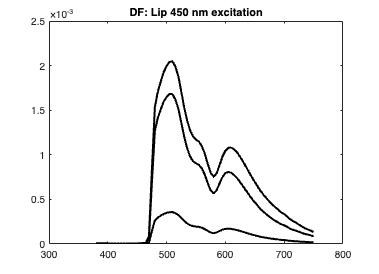


ieNewGraphWin; 
D_lip = ieReadSpectra('spd-2024-03-19-D_450nm_lip_90mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_450nm_lip_480mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
D_lip = ieReadSpectra('spd-2024-03-19-D_450nm_lip_870mA.mat',waves);   plot(waves,D_lip,'k','LineWidth',2); hold on;
title('DF: Lip 450 nm excitation');

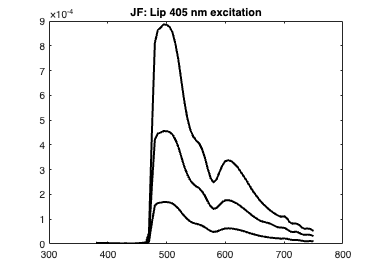


% Joyce
ieNewGraphWin; 
J_lip = ieReadSpectra('spd-2024-03-12-11-405nm-J-lip-90mA.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-405nm-J-lip-560mA.mat',waves);  plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-405nm-J-lip-980mA.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
title('JF: Lip 405 nm excitation');

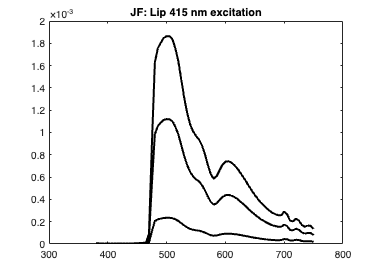


ieNewGraphWin; 
J_lip = ieReadSpectra('spd-2024-03-12-11-415nm-J-lip-80mA.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-415nm-J-lip-460mA.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-415nm-J-lip-910mA.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
title('JF: Lip 415 nm excitation');

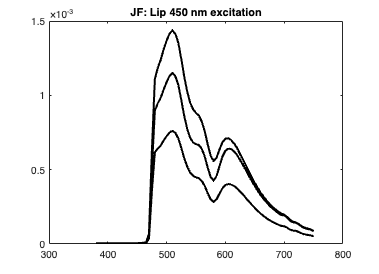


ieNewGraphWin; 
J_lip = ieReadSpectra('spd-2024-03-12-11-450nm-J-lip-90mA.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-450nm-J-lip-460nm.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
J_lip = ieReadSpectra('spd-2024-03-12-11-450nm-J-lip-870mA.mat',waves);   plot(waves,J_lip,'k','LineWidth',2); hold on;
title('JF: Lip 450 nm excitation');